nvar = 2;
fun = @Shubert2_fun;
% Creation function 'gacreationlinearfeasible' and Mutation function
% 'mutationpositivebasis' gave best result so far, with -186.7304 at
% [-0.8008, 4.8581]. Global minima is -186.730909


Single objective optimization:
2 Variable(s)

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossovertwopoint
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              100          -100.3           10.56        0
    2              147          -147.3          -14.68        0
    3              194          -147.3          -64.57        1
    4              241          -164.1          -90.95        0
    5              288          -164.1          -84.42        1
    6              335          -164.1           3.257        2
    7              382          -164.1          -33.82        3
    8              429            -176          -25.77        0
    9              476            -176          -20.59        1
   10              523          -178.5          -152.5        0
   11   

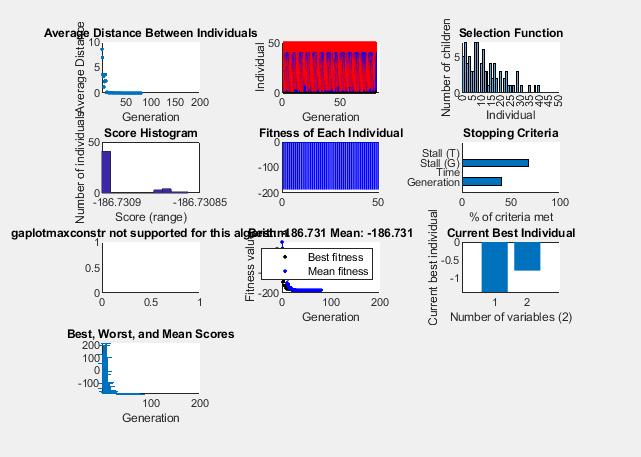

% Set nondefault solver options
options = optimoptions("ga","CrossoverFcn","crossovertwopoint",...
    "SelectionFcn","selectiontournament","PopulationSize",50,"CreationFcn",...
    "gacreationuniformint","MutationFcn","mutationadaptfeasible","Display",...
    "iter","PlotFcn",["gaplotdistance","gaplotgenealogy","gaplotselection",...
    "gaplotscorediversity","gaplotscores","gaplotstopping","gaplotmaxconstr",...
    "gaplotbestf","gaplotbestindiv","gaplotrange"]);

% Solve
[solution,objectiveValue] = ga(fun,nvar,[],[],[],[],repmat(-10,nvar,1),...
    repmat(10,nvar,1),[],[],options);


% Clear variables
clearvars options

